# Signal Processing for a non-stationary signal

Author: Vishu Sharma

Description: Code to calculate  FFT and spectogram of a non-stationary signal

Last Modified: 12.12.2023

clear all, clc

%% Audio recording 
[x, Fs] = audioread("D:\University of Siegen\uos\research Project\Codes\sounds\578626main_sputnik-beep.mp3");

L = length(x)             % length of signal

L = 210288

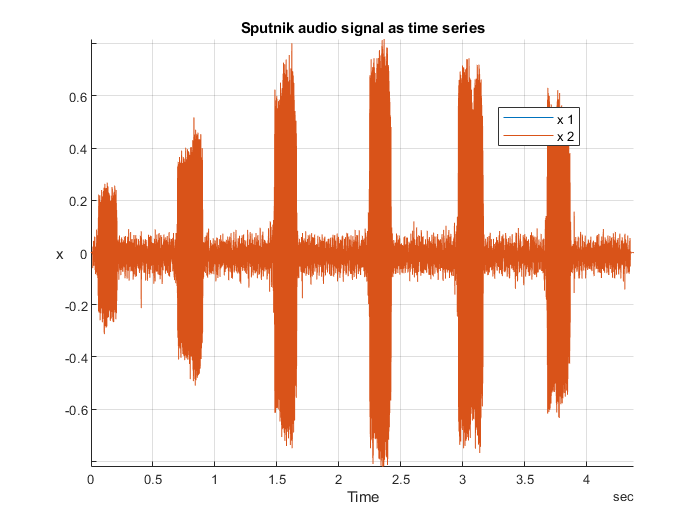

Audio_sample = timetable(x,'SampleRate',Fs);

ax = gca;
ax.FontSize = 16;
stackedplot(Audio_sample);
title('Sputnik audio signal as time series' ...
    )
grid on

## Fast Fourier transform

T= 1/Fs;                  % sampling period
t = (0:L-1)*T;            % time vector
n = 2^nextpow2(L)         % num of points for FFT

n = 262144



Y = fft(x);
P2 = abs(Y/L);
P1 = P2(1:L/2+1);
P1(2:end-1) = 2*P1(2:end-1);
f = Fs*(0:(L/2))/L

f = 	1.0e+04 *

         0    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006    0.0006    0.0007    0.0007    0.0007    0.0007    0.0008    0.0008    0.0008    0.0008    0.0008    0.0009    0.0009    0.0009    0.0009    0.0010    0.0010    0.0010    0.0010    0.0010    0.0011    0.0011    0.0011


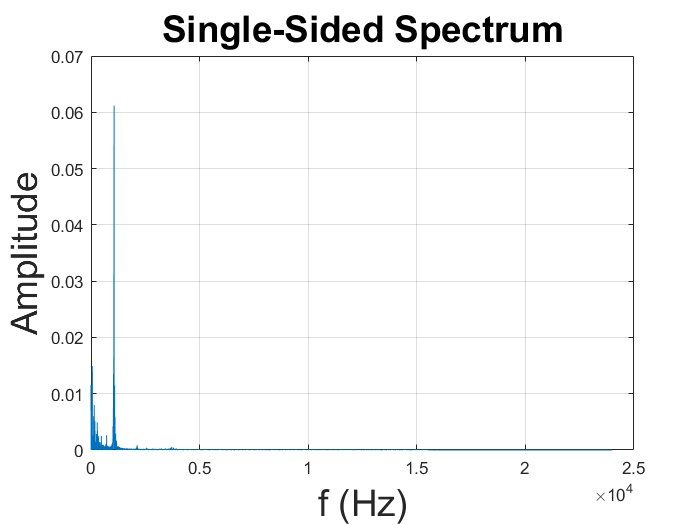


plot(f,P1) 
title('Single-Sided Spectrum','FontSize', 22)
xlabel('f (Hz)','FontSize', 22)
ylabel('Amplitude', 'FontSize', 22)

grid on

## Spectogram

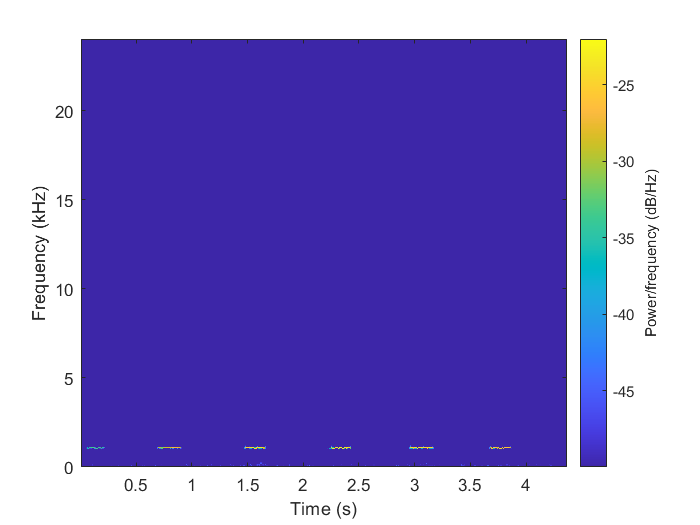

z = x(:,1);
s = spectrogram(z);
spectrogram(z, blackman(1024), 512, 1024, Fs,'yaxis', 'reassign','MinThreshold', -50)

## PSD

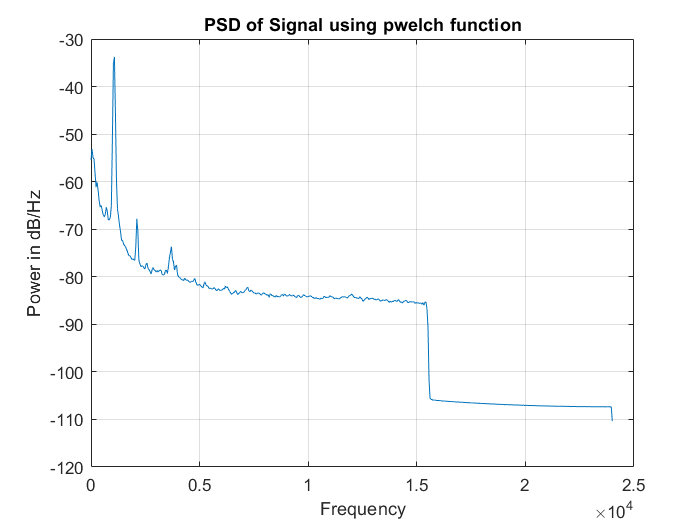

[pxx,f1] = pwelch(z,1024,512,1024,Fs, 'onesided','psd');
plot(f1,10*log10(pxx))
title('PSD of Signal using pwelch function')
xlabel('Frequency')
ylabel('Power in dB/Hz')
grid on

## Waterfall Plot

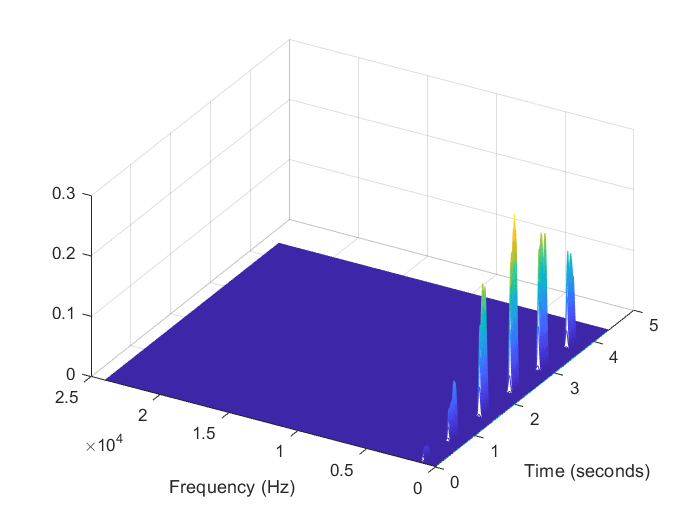

[p,f2,t1] = pspectrum(z,Fs,'spectrogram');

waterfall(f2,t1,p')
xlabel('Frequency (Hz)')
ylabel('Time (seconds)')
wtf = gca;
wtf.XDir = 'reverse';
view([30 45])

## HHT

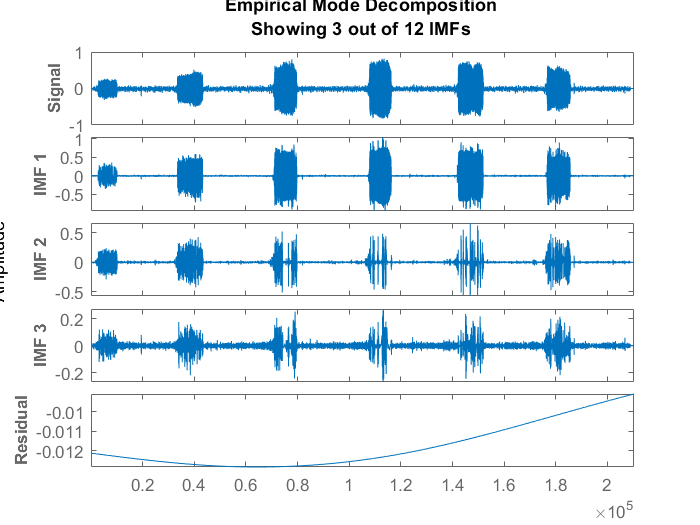

emd(z,'MaxNumIMF',12)

imf = emd(z,'Display',12);

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        1     |      0.16973   |  SiftMaxRelativeTolerance
      2      |        2     |     0.082831   |  SiftMaxRelativeTolerance
      3      |        2     |     0.044141   |  SiftMaxRelativeTolerance
      4      |        2     |     0.086894   |  SiftMaxRelativeTolerance
      5      |        2     |     0.079781   |  SiftMaxRelativeTolerance
      6      |        2     |      0.03833   |  SiftMaxRelativeTolerance
      7      |        2     |     0.055903   |  SiftMaxRelativeTolerance
      8      |        2     |     0.025724   |  SiftMaxRelativeTolerance
      9      |        2     |       0.1019   |  SiftMaxRelativeTolerance
     10      |        2     |      0.16955   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


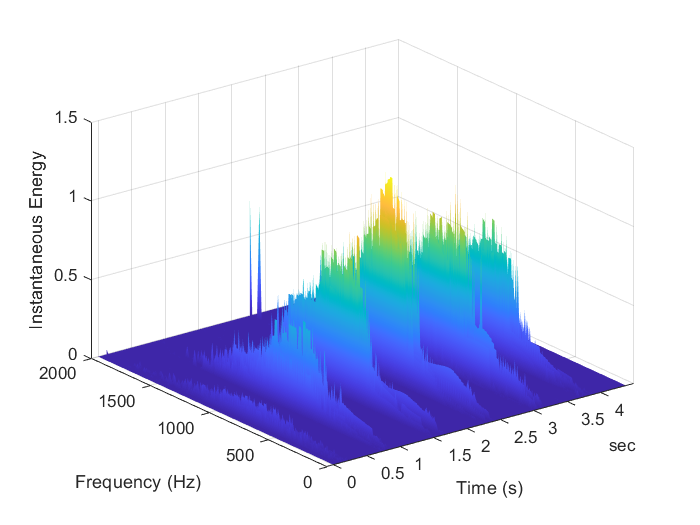

[hs,F,t] = hht(imf,Fs,'FrequencyLimits',[0 2000]);

mesh(seconds(t),F,hs,'EdgeColor','none','FaceColor','interp')
xlabel('Time (s)')
ylabel('Frequency (Hz)')
zlabel('Instantaneous Energy')